% For reproducibility
rng(0); 
rand(0);
OUTPUT_CLASSESS = 2

OUTPUT_CLASSESS = 2

addpath(genpath('./functions'))


ds_IMG_SIZE_224 = [224 224 3];
ds_IMG_SIZE_227 = [227 227 3];
ds_IMG_SIZE_299 = [299 299 3];
ds_IMG_SIZE_256 = [256 256 3];
ds_IMG_SIZE_384 = [384 384 3];

DS_SPLIT_RATIO = [0.7, 0.2, 0.1]; 

dataset_base_path = "ISIC/dataset/"; %dataset to use
experimentation_name = "peerj_isic_iimp"; %experimentation name

datastore_224_ds = imageDatastore(dataset_base_path,"LabelSource","foldernames",IncludeSubfolders=true,ReadFcn=@customDataReader224);
datastore_227_ds = imageDatastore(dataset_base_path,"LabelSource","foldernames",IncludeSubfolders=true,ReadFcn=@customDataReader227);
datastore_256_ds = imageDatastore(dataset_base_path,"LabelSource","foldernames",IncludeSubfolders=true,ReadFcn=@customDataReader256);
datastore_299_ds = imageDatastore(dataset_base_path,"LabelSource","foldernames",IncludeSubfolders=true,ReadFcn=@customDataReader299);
datastore_384_ds = imageDatastore(dataset_base_path,"LabelSource","foldernames",IncludeSubfolders=true,ReadFcn=@customDataReader384);



[dataset_224_train,dataset_224_validation,dataset_224_test] = splitEachLabel(datastore_224_ds,DS_SPLIT_RATIO(1),DS_SPLIT_RATIO(2),DS_SPLIT_RATIO(3));
[dataset_256_train,dataset_256_validation,dataset_256_test] = splitEachLabel(datastore_256_ds,DS_SPLIT_RATIO(1),DS_SPLIT_RATIO(2),DS_SPLIT_RATIO(3));
[dataset_227_train,dataset_227_validation,dataset_227_test] = splitEachLabel(datastore_227_ds,DS_SPLIT_RATIO(1),DS_SPLIT_RATIO(2),DS_SPLIT_RATIO(3));
[dataset_299_train,dataset_299_validation,dataset_299_test] = splitEachLabel(datastore_299_ds,DS_SPLIT_RATIO(1),DS_SPLIT_RATIO(2),DS_SPLIT_RATIO(3));
[dataset_384_train,dataset_384_validation,dataset_384_test] = splitEachLabel(datastore_384_ds,DS_SPLIT_RATIO(1),DS_SPLIT_RATIO(2),DS_SPLIT_RATIO(3));




%set to 1 the experiment you want to execute

exec_EXPS=[
    % <NetworkName> NoPreProc Kdr224
    1 %Alexnet 
    0 %GoogleNet 
    0 %densenet201
    0 %Resnet18
    0 %MobilenetV2 
    0 %SqueezeNet 
    0 %ShuffleNet 
    0 %Resnet50 
    0 %Resnet101
    0 %Nasnetmobile
    0 %EfficientNetB0
    0 %VGG16
    0 %VGG19
    0 %InceptionV3
    0 %xception
    0 %InceptionResnetV2
    0 %nasnetlarge (non addestrabile sulla macchina in lab)
    0 %darknet19
    0 %darknet53
    0 %Vision Transformer 
]; 




% Data augmentation settings 

pixelRange = [-180 180];
scale_pixelRange = [1 30];

imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    RandXScale=scale_pixelRange, ...
    RandYScale=scale_pixelRange);


dataset_224_augimdsTrain = augmentedImageDatastore(ds_IMG_SIZE_224(1:2),dataset_224_train, ...
    'DataAugmentation',imageAugmenter);
dataset_224_augimdsValidation = augmentedImageDatastore(ds_IMG_SIZE_224(1:2),dataset_224_validation);


dataset_227_augimdsTrain = augmentedImageDatastore(ds_IMG_SIZE_227(1:2),dataset_227_train, ...
    'DataAugmentation',imageAugmenter);
dataset_227_augimdsValidation = augmentedImageDatastore(ds_IMG_SIZE_227(1:2),dataset_227_validation);

dataset_256_augimdsTrain = augmentedImageDatastore(ds_IMG_SIZE_256(1:2),dataset_256_train, ...
    'DataAugmentation',imageAugmenter);
dataset_256_augimdsValidation = augmentedImageDatastore(ds_IMG_SIZE_256(1:2),dataset_256_validation);

dataset_299_augimdsValidation = augmentedImageDatastore(ds_IMG_SIZE_299(1:2),dataset_299_train, ...
    'DataAugmentation',imageAugmenter);
kdr299_augimdsValidation = augmentedImageDatastore(ds_IMG_SIZE_299(1:2),dataset_299_validation);

dataset_384_augimdsTrain = augmentedImageDatastore(ds_IMG_SIZE_384(1:2),dataset_384_train, ...
    'DataAugmentation',imageAugmenter);
dataset_384_augimdsValidation = augmentedImageDatastore(ds_IMG_SIZE_384(1:2),dataset_384_validation);


opengl('save','software')       


    % Experimentation on KDR224 images (preprocessed as described in [1])
    datasets224 = {dataset_224_train , dataset_224_validation, dataset_224_test};
    datasets224_da = {dataset_224_augimdsTrain,dataset_224_augimdsValidation,dataset_224_test};
    
    datasets227 = {dataset_227_train , dataset_227_validation, dataset_227_test};
    datasets227_da = {dataset_227_augimdsTrain,dataset_227_augimdsValidation,dataset_227_test};
    
    datasets256 = {dataset_256_train , dataset_256_validation, dataset_256_test};
    datasets256_da = {dataset_256_augimdsTrain,dataset_256_augimdsValidation,dataset_256_test};

    datasets299 = {dataset_299_train , dataset_299_validation, dataset_299_test};
    datasets299_da = {dataset_299_augimdsValidation,kdr299_augimdsValidation,dataset_299_test};

    datasets384 = {dataset_384_train , dataset_384_validation, dataset_384_test};
    datasets384_da = {dataset_384_augimdsTrain,dataset_384_augimdsValidation,dataset_384_test};

Experiment:peerj_isic_iimp_alexnet_noprec


VALccuracy = 84.8870

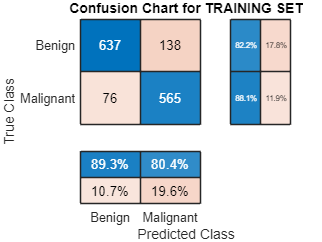

VALccuracy = 87.3762

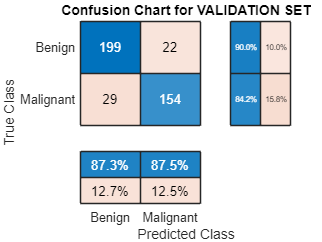

VALccuracy = 80.6931

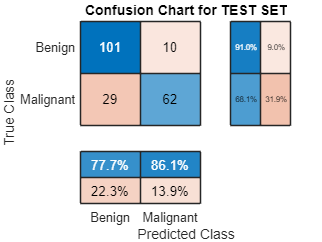

%ALEXNET
if exec_EXPS(1)==1
    [alexnet_scratch,alexnet_tl,alexnet_ft] = prepare_alexnet(ds_IMG_SIZE_227,OUTPUT_CLASSESS,10,10,1,1);
    trained_alexnet_networs= execute_experiment(strcat(experimentation_name,"_alexnet_noprec"),experimentation_name,datasets227,datasets227_da,DS_SPLIT_RATIO,"alexnet",[alexnet_scratch,alexnet_tl,alexnet_ft]);
end 

%GOOGLENET
if exec_EXPS(2)==1
    % Prepare the networks
    [googlenet_scratch,googlenet_tl,googlenet_ft] = prepare_googlenet(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_googlenet_networs= execute_experiment(strcat(experimentation_name,"_googlenet_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"googlenet",[googlenet_scratch,googlenet_tl,googlenet_ft]);
end 

%DETNSET201
if exec_EXPS(3)==1
    % Prepare the networks
    [densenet_scratch,densenet_tl,densenet_ft] = prepare_densenet201(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_densenet_networs= execute_experiment(strcat(experimentation_name,"_densenet_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"densenet",[densenet_scratch,densenet_tl,densenet_ft]);
end 


%RESNET18
if exec_EXPS(4)==1
    % Prepare the networks
    [resnet18_scratch,resnet18_tl,resnet18_ft] = prepare_resnet18(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_resnet18_networs= execute_experiment(strcat(experimentation_name,"_densenet_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"resnet18",[resnet18_scratch,resnet18_tl,resnet18_ft]);
end 

%MOBILENETV2
if exec_EXPS(5)==1
    % Prepare the networks
    [mobilenetv2_scratch,mobilenetv2_tl,mobilenetv2_ft] = prepare_mobilenetv2(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_mobilenetv2_networs= execute_experiment(strcat(experimentation_name,"_mobilenetv2_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"mobilenetv2",[mobilenetv2_scratch,mobilenetv2_tl,mobilenetv2_ft]);
end 

%SQUEEZENET
if exec_EXPS(6)==1
    % Prepare the networks
    [squeezenet_scratch,squeezenet_tl,squeezenet_ft] = prepare_squeezenet(ds_IMG_SIZE_227,OUTPUT_CLASSESS,10,10,1,1);
    trained_squeezenet_networs= execute_experiment(strcat(experimentation_name,"_mobilenetv2_noprec"),experimentation_name,datasets227,datasets227_da,DS_SPLIT_RATIO,"squeezenet",[squeezenet_scratch,squeezenet_tl,squeezenet_ft]);
end 

%SHUFFLENET
if exec_EXPS(7)==1
    % Prepare the networks
    [shufflenet_scratch,shufflenet_tl,shufflenet_ft] = prepare_shufflenet(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_shufflenet_networs= execute_experiment(strcat(experimentation_name,"_shufflenet_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"shufflenet",[shufflenet_scratch,shufflenet_tl,shufflenet_ft]);
end 

%RESNET50
if exec_EXPS(8)==1
    % Prepare the networks
     [resnet50_scratch,resnet50_tl,resnet50_ft] = prepare_resnet50(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_resnet50_networs= execute_experiment(strcat(experimentation_name,"_resnet50_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"resnet50",[resnet50_scratch,resnet50_tl,resnet50_ft]);
end 

%RESNET101
if exec_EXPS(9)==1
    % Prepare the networks
     [resnet101_scratch,resnet101_tl,resnet101_ft] = prepare_resnet101(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_resnet101_networs= execute_experiment(strcat(experimentation_name,"_resnet101_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"resnet101",[resnet101_scratch,resnet101_tl,resnet101_ft]);
end 

%NASNETMOBILE
if exec_EXPS(10)==1
    % Prepare he networks
     [nasnetmobile_scratch,nasnetmobile_tl,nasnetmobile_ft] = prepare_nasnetmobile(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_nasnetmobile_networs= execute_experiment(strcat(experimentation_name,"_nasnetmobile_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"nasnetmobile",[nasnetmobile_scratch,nasnetmobile_tl,nasnetmobile_ft]);
end 

%EFFICIENTNETB0
if exec_EXPS(11)==1
    % Prepare he networks
     [efficientnetb0_scratch,efficientnetb0_tl,efficientnetb0_ft] = prepare_efficientnetb0(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_efficientnetb0_networs= execute_experiment(strcat(experimentation_name,"_efficientnetb0_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"efficientnetb0",[efficientnetb0_scratch,efficientnetb0_tl,efficientnetb0_ft]);
end 

Experiment:peerj_isic_iimp_vgg16_noprec


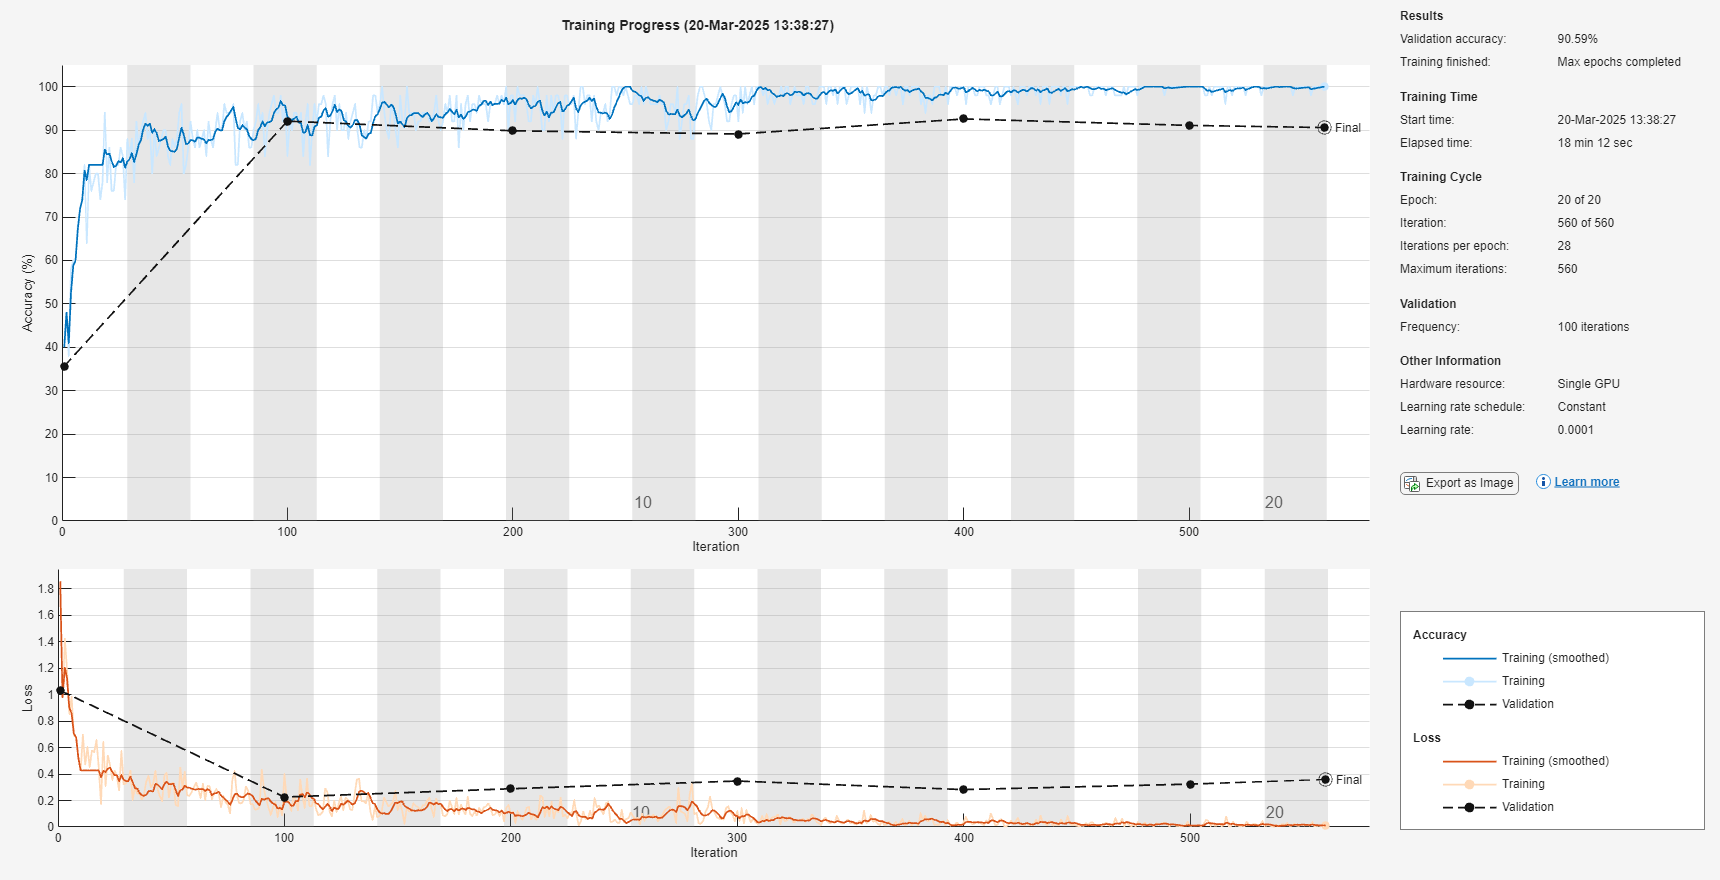

VALccuracy = 100

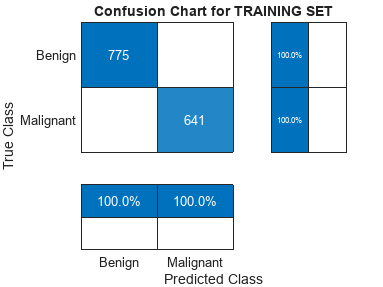

VALccuracy = 90.5941

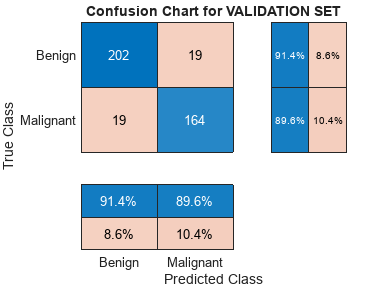

VALccuracy = 80.6931

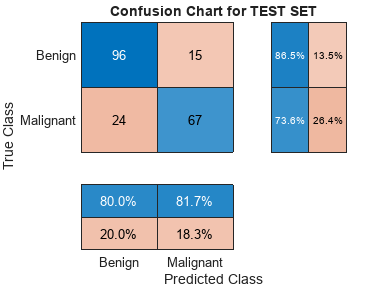

%VGG16
if exec_EXPS(12)==1
    % Prepare he networks
     [vgg16_scratch,vgg16_tl,vgg16_ft] = prepare_vgg16(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_vgg16_networs= execute_experiment(strcat(experimentation_name,"_vgg16_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"vgg16",[vgg16_scratch,vgg16_tl,vgg16_ft]);
end 

Experiment:peerj_isic_iimp_vgg19_noprec


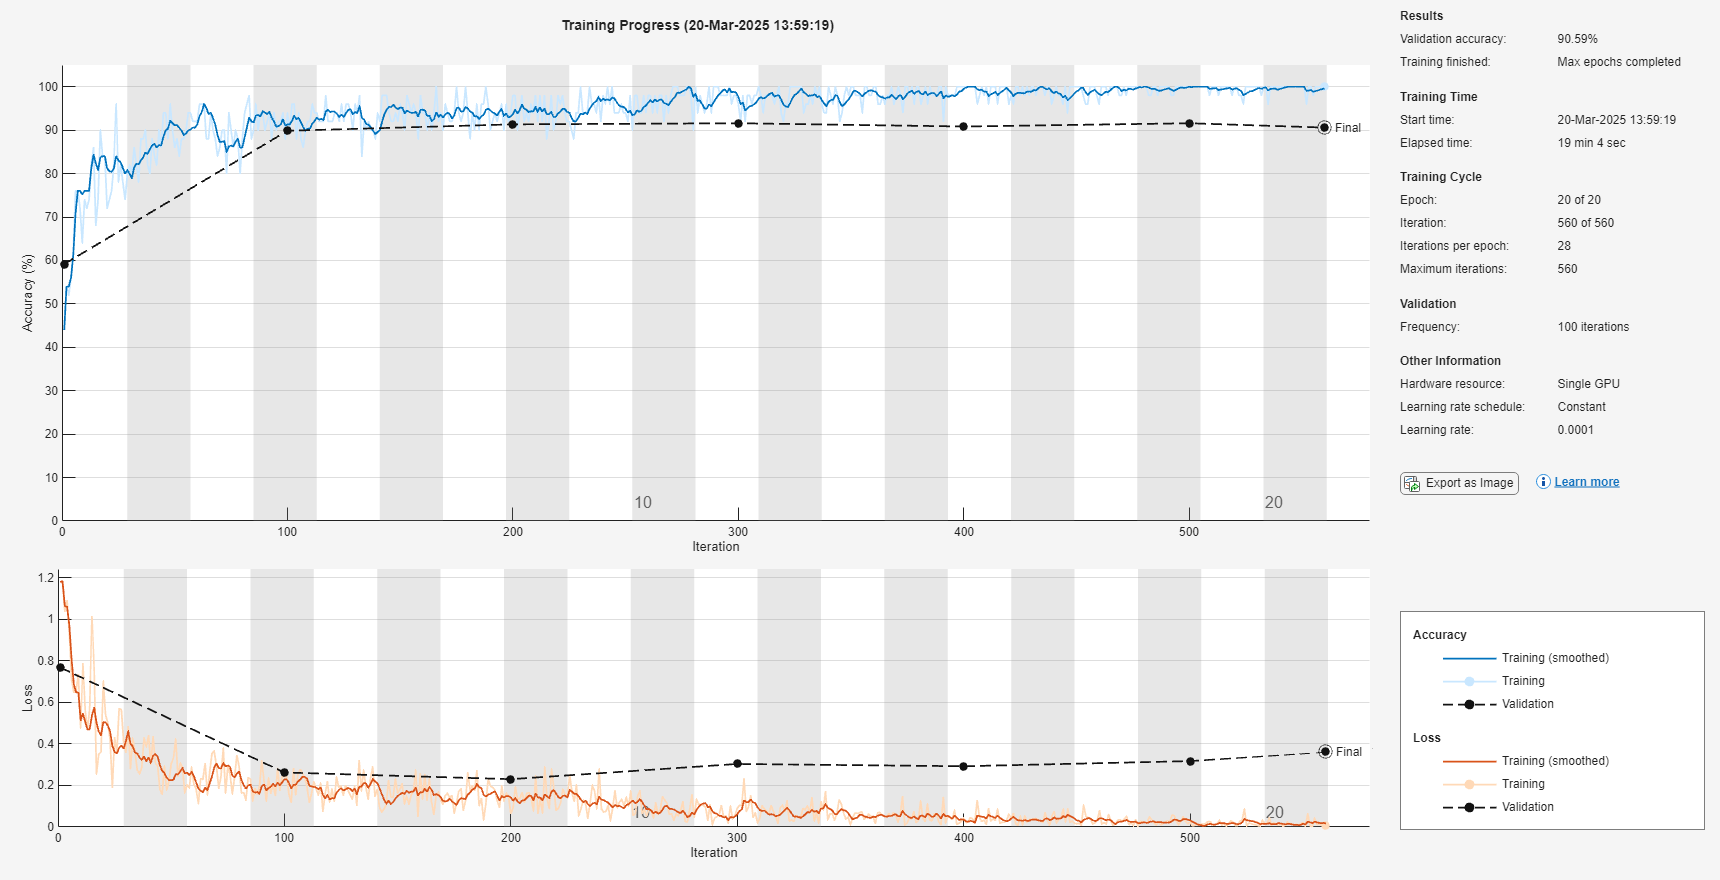

VALccuracy = 100

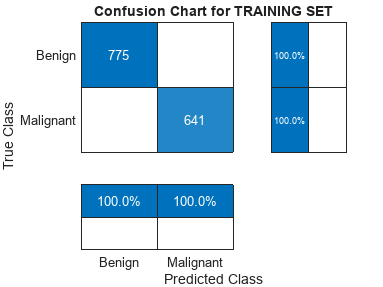

VALccuracy = 90.5941

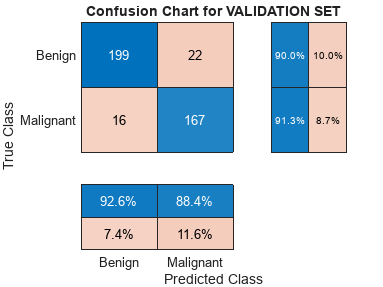

VALccuracy = 78.7129

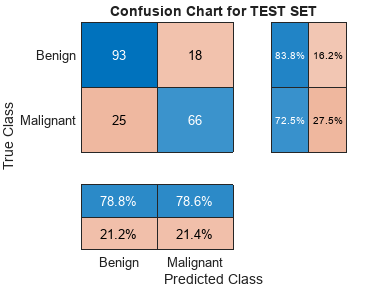

%VGG19
if exec_EXPS(13)==1
    % Prepare he networks
     [vgg19_scratch,vgg19_tl,vgg19_ft] = prepare_vgg19(ds_IMG_SIZE_224,OUTPUT_CLASSESS,10,10,1,1);
    trained_vgg19_networs= execute_experiment(strcat(experimentation_name,"_vgg19_noprec"),experimentation_name,datasets224,datasets224_da,DS_SPLIT_RATIO,"vgg19",[vgg19_scratch,vgg19_tl,vgg19_ft]);
end 


%InceptionV3 (funziona a 299x299)
if exec_EXPS(14)==1
    % Prepare the networks
     [inceptionv3_scratch,inceptionv3_tl,inceptionv3_ft] = prepare_inceptionv3(ds_IMG_SIZE_299,OUTPUT_CLASSESS,10,10,1,1);
    trained_vinceptionv3_networs= execute_experiment(strcat(experimentation_name,"_inceptionv3_noprec"),experimentation_name,datasets299,datasets299_da,DS_SPLIT_RATIO,"inceptionv3",[inceptionv3_scratch,inceptionv3_tl,inceptionv3_ft]);
end 

%xception (funziona a 299x299)
if exec_EXPS(15)==1
    % Prepare the networks
     [xception_scratch,xception_tl,xception_ft] = prepare_xception(ds_IMG_SIZE_299,OUTPUT_CLASSESS,10,10,1,1);
    trained_vxception_networs= execute_experiment(strcat(experimentation_name,"_xception_noprec"),experimentation_name,datasets299,datasets299_da,DS_SPLIT_RATIO,"xception",[xception_scratch,xception_tl,xception_ft]);
end 

%xception (funziona a 299x299)
if exec_EXPS(16)==1
    % Prepare the networks
     [inceptionresnetv2_scratch,inceptionresnetv2_tl,inceptionresnetv2_ft] = prepare_xception(ds_IMG_SIZE_299,OUTPUT_CLASSESS,10,10,1,1);
    trained_inceptionresnetv2_networs= execute_experiment("kdr224_inceptionresnetv2_noprec",experimentation_name,datasets299,datasets299_da,DS_SPLIT_RATIO,"inceptionresnetv2",[inceptionresnetv2_scratch,inceptionresnetv2_tl,inceptionresnetv2_ft]);
end 

%nasnetlarge (funziona a 256x256)
if exec_EXPS(17)==1
    % Prepare the networks
     [nasnetlarge_scratch,nasnetlarge_tl,nasnetlarge_ft] = prepare_nasnetlarge(ds_IMG_SIZE_256,OUTPUT_CLASSESS,10,10,1,1);
    trained_nasnetlarge_networs= execute_experiment(strcat(experimentation_name,"_nasnetlarge_noprec"),experimentation_name,datasets256,datasets256_da,DS_SPLIT_RATIO,"inceptionresnetv2",[nasnetlarge_scratch,nasnetlarge_tl,nasnetlarge_ft]);
end 

%darknet19 (256x256)
if exec_EXPS(18)==1
    % Prepare the networks
     [darknet19_scratch,darknet19_tl,darknet19_ft] = prepare_darknet19(ds_IMG_SIZE_256,OUTPUT_CLASSESS,10,10,1,1);
    trained_darknet19_networs= execute_experiment(strcat(experimentation_name,"_darknet19_noprec"),experimentation_name,datasets256,datasets256_da,DS_SPLIT_RATIO,"inceptionresnetv2",[darknet19_scratch,darknet19_tl,darknet19_ft]);
end 

%darknet53 (256x256)
if exec_EXPS(19)==1
    % Prepare the networks
    [darknet53_scratch,darknet53_tl,darknet53_ft] = prepare_darknet53(ds_IMG_SIZE_256,OUTPUT_CLASSESS,10,10,1,1);
    trained_darknet53_networs= execute_experiment(strcat(experimentation_name,"_darknet53_noprec"),experimentation_name,datasets256,datasets256_da,DS_SPLIT_RATIO,"inceptionresnetv2",[darknet53_scratch,darknet53_tl,darknet53_ft]);
end 
